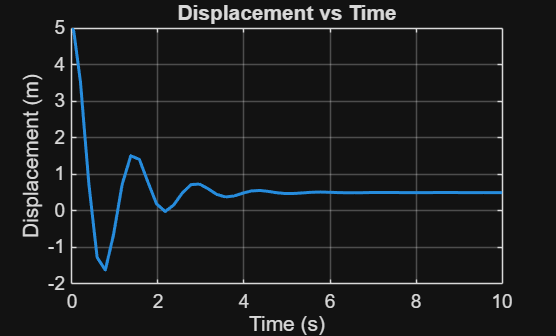

%% Spring-Mass-Damper MATLAB + Simulink

clc; clear; close all

% PARAMETERS (MATLAB controls Simulink)
m = 1;      % mass (kg)
c = 2;      % damping
k = 20;     % stiffness
F = 10;     % force

% RUN SIMULATION
simOut = sim('SpringMassModel');
% EXTRACT DATA
t = simOut.tout;
x = simOut.x;   % from To Workspace block
% ANALYSIS
% Velocity (numerical)
v = gradient(x, t);
% Damping ratio
zeta = c / (2*sqrt(m*k));
if zeta < 1
    type = 'Underdamped';
elseif zeta == 1
    type = 'Critically damped';
else
    type = 'Overdamped';
end

% Steady-state value (theoretical)
x_ss = F / k;
% PLOTS
% Plot displacement versus time
figure
% Draw line with thicker stroke for visibility
plot(t, x, 'LineWidth', 1.5)
title('Displacement vs Time')
xlabel('Time (s)')
ylabel('Displacement (m)')
grid on

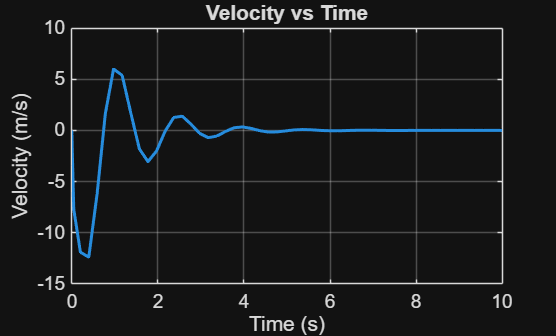


% Plot velocity versus time with thick line and grid
figure
plot(t, v, 'LineWidth', 1.5)
title('Velocity vs Time')
xlabel('Time (s)')
ylabel('Velocity (m/s)')
grid on


% OUTPUT
fprintf('\n--- System Results ---\n') %Header for results


--- System Results ---


fprintf('Damping Ratio: %.3f\n', zeta) %Damping ratio figure

Damping Ratio: 0.224


fprintf('System Type: %s\n', type) %System type

System Type: Underdamped


fprintf('Steady-State Displacement: %.3f m\n', x_ss) %Steady state displacement

Steady-State Displacement: 0.500 m
